# Brachistonchrone Problem

Final Time Given:

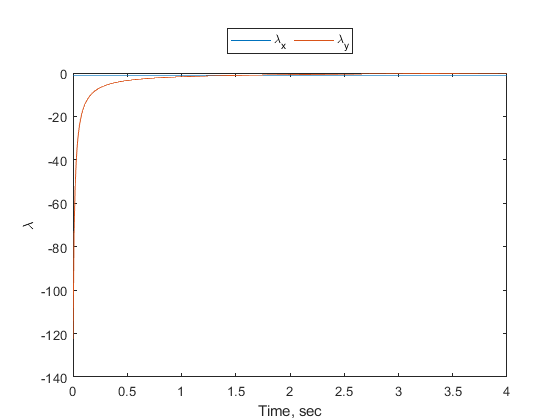

clear
clc
tf = 4; % sec, final time
g = 9.81; % m/s^2, gravity
r = 48; % m, radius of circular guess
[T,S] = ode45(@(t,s)eom(t,s,g,r),linspace(0,4,401),[0,1e-3]);
figure(1)
plot(S(:,1),S(:,2),'-k')
xlabel('x, m')
ylabel('y, m')
set(gca,'YDir','reverse')
axis equal
[T2,Lambda] = ode45(@(t,s)LagrangeEom(t,s,g,r,T,S),T(end:-1:1),[-1,0]);
figure(2)
plot(T2,Lambda)
xlabel('Time, sec')
ylabel('\lambda')
legend('\lambda_x','\lambda_y','Location','NorthOutside','Orientation','horizontal')

Guess Structure

solinit.x = T;
solinit.y = [S,Lambda(end:-1:1,:)]';

BVP4C calling statement:

sol = bvp4c(@(t,s)ELeom(t,s,g),@bcfunc,solinit)

sol = struct with fields:
    solver: 'bvp4c'
         x: [1×270 double]
         y: [4×270 double]
        yp: [4×270 double]
     stats: [1×1 struct]


figure(1)
hold on
plot(sol.y(1,:),sol.y(2,:),'-b')

Analytical solution:

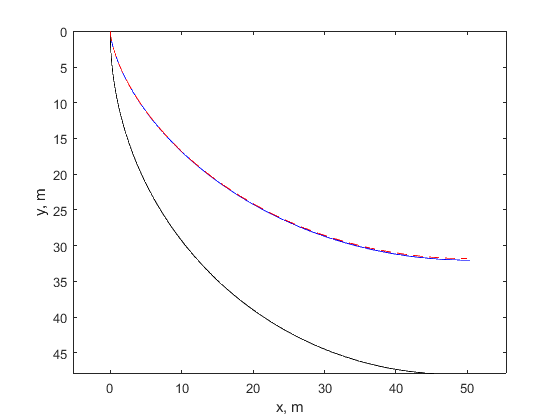

x = g*tf^2/pi^2*(pi*sol.x/tf-sin(pi*sol.x/tf));
y = g*tf^2/pi^2*(1-cos(pi*sol.x/tf));
plot(x,y,'--r')

Subfunctions:

Integrate states (x,y) forward in time

function ds = eom(~,s,g,r)
% s(1) = x, s(2) = y
theta = pi/2-atan2(s(2),r-s(1));
ds(1) = sqrt(2*g*s(2))*cos(theta);
ds(2) = sqrt(2*g*s(2))*sin(theta);
ds = ds';
end

Integrate Lagrange Multipliers backward in time

function ds = LagrangeEom(t,s,g,r,T,SXY)
% s(1) = lambda_x, s(2) = lambda_y
XY = interp1(T,SXY,t);
theta = pi/2-atan2(XY(2),r-XY(1));
ds(1) = 0;
ds(2) = -sqrt(g/(2*XY(2)))*(s(1)*cos(theta)+s(2)*sin(theta));
ds = ds';
end

Euler-Lagrange Equations:

function ds = ELeom(~,s,g)
% s(1) = x, s(2) = y, s(3) = Lambda_x, s(4) = Lambda_y
theta = atan2(-s(4),-s(3)); % optimal control law
ds(1) = sqrt(2*g*s(2))*cos(theta);
ds(2) = sqrt(2*g*s(2))*sin(theta);
ds(3) = 0;
ds(4) = -sqrt(g/(2*s(2)))*(s(3)*cos(theta)+s(4)*sin(theta));
ds = ds';
end

Boundary Condition Function

function con = bcfunc(so,sf)
% so is the initial states
% sf is the final states
con(1) = so(1); % x(0) = 0
con(2) = so(2)-1e-3; % y(0) = 1e-3
con(3) = sf(3)+1; % Lambda_x(tf) = -1
con(4) = sf(4); % Lambda_y(tf) = 0
end